% Auto-generated by cameraCalibrator app on 16-Apr-2021
%-------------------------------------------------------


% Define images to process
imageFileNames = {
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image1.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image2.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image3.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image4.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image5.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image6.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image7.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image8.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image9.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image10.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image11.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image12.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image13.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image14.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image15.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image16.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image19.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image20.jpg',...
    'F:\UNIVERSITY\4TH_SEM\3 EN2550 - Fundamentals of Image Processing and Machine Vision\Computer-Vision-and-Image-Processing\SINGLE VIEW GEOMETRY\Camera Calibration\laptop_cam\Image21.jpg',...
    };
% Detect checkerboards in images
[imagePoints, boardSize, imagesUsed] = detectCheckerboardPoints(imageFileNames);

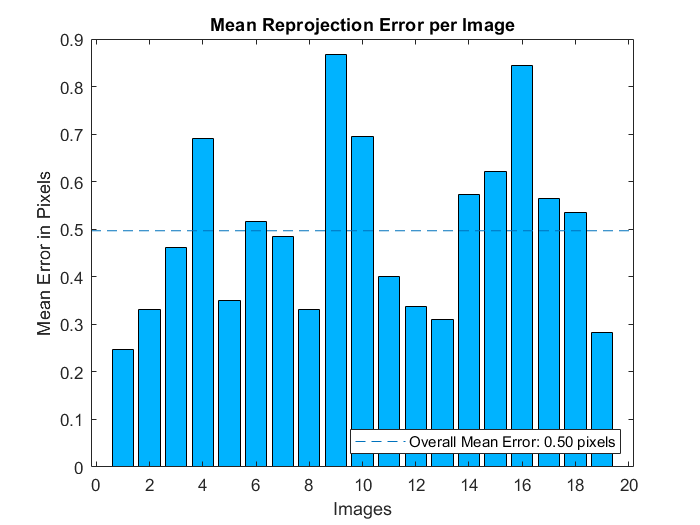

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates of the corners of the squares
squareSize = 30;  % in units of 'millimeters'
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

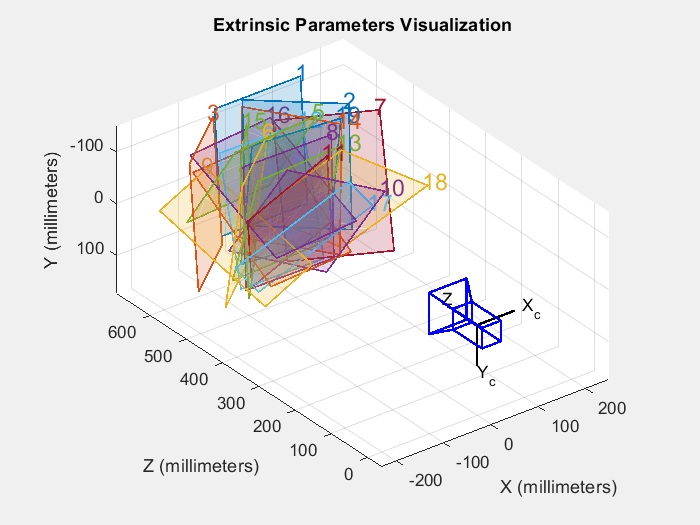


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  950.2569 +/- 1.2369      953.0092 +/- 1.2973  ]
Principal point (pixels):[  631.3673 +/- 0.8360      372.1849 +/- 0.7246  ]
Radial distortion:       [    0.0233 +/- 0.0053       -0.0725 +/- 0.0227  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0461 +/- 0.0043        0.0667 +/- 0.0043        1.5634 +/- 0.0004  ]
                         [    0.5741 +/- 0.0017        0.6283 +/- 0.0016        1.4713 +/- 0.0005  ]
                         [   -0.6167 +/- 0.0019       -0.4756 +/- 0.0020        1.5209 +/- 0.0005  ]
                         [   -0.8125 +/- 0.0013        0.6973 +/- 0.0013        1.4055 +/- 0.0006  ]
                         [    0.4280 +/- 0.0018       -0.5052 +/- 0.0018        1.5017 +/- 0.0005  ]
                         [   -0.4390 +/- 0.0017       -0.6215 +/- 0.0017        1.5408 +/- 0.0005  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')
